# Ising Model 2D

## Import data 1

%path="../../../cmake-build-release/bin/IsingResults.tsv";
path="./IsingResultsNew2.tsv";
%path="./IsingResults_from_headless_system.tsv";

numOfTemps=readmatrix(path,"FileType","text","Delimiter","\t","Range",'B1:B1')

numOfTemps = 32

numOfIterations=readmatrix(path,"FileType","text","Delimiter","\t","Range",'B2:B2')

numOfIterations = 10000

it=numOfTemps*numOfIterations;

[N1, temp1, mag1, en1, ~, ~] = importfile(path,1,it);
[N2, temp2, mag2, en2, ~, ~] = importfile(path,it+1,2*it);
[N3, temp3, mag3, en3, ~, ~] = importfile(path,2*it+1,3*it);
[N4, temp4, mag4, en4, ~, ~] = importfile(path,3*it+1,4*it);
[N5, temp5, mag5, en5, ~, ~] = importfile(path,4*it+1,5*it);

## Import data 2

%path="../../../cmake-build-release/bin/IsingResults.tsv";
path="./IsingResults2.tsv";
%path="./IsingResults_from_headless_system.tsv";


%[temp1, en1,mag1] = importfileAppend(path,temp1,en1,mag1);
%[temp2, en2,mag2] = importfileAppend(path,temp2,en2,mag2);
%[temp3, en3,mag3] = importfileAppend(path,temp3,en3,mag3);
%[temp4, en4,mag4] = importfileAppend(path,temp4,en4,mag4);
%[temp5, en5,mag5] = importfileAppend(path,temp5,en5,mag5);

## Energy: Reduce data to mean and std

reduce data now

[en1_mean,en1_std,en1_var,en1_var_err,en1_weight,en1_corr] = ReduceObservable(en1,temp1);
[en2_mean,en2_std,en2_var,en2_var_err,en2_weight,en2_corr] = ReduceObservable(en2,temp2);
[en3_mean,en3_std,en3_var,en3_var_err,en3_weight,en3_corr] = ReduceObservable(en3,temp3);
[en4_mean,en4_std,en4_var,en4_var_err,en4_weight,en4_corr] = ReduceObservable(en4,temp4);
[en5_mean,en5_std,en5_var,en5_var_err,en5_weight,en5_corr] = ReduceObservable(en5,temp5);
temp_red=unique(temp1);

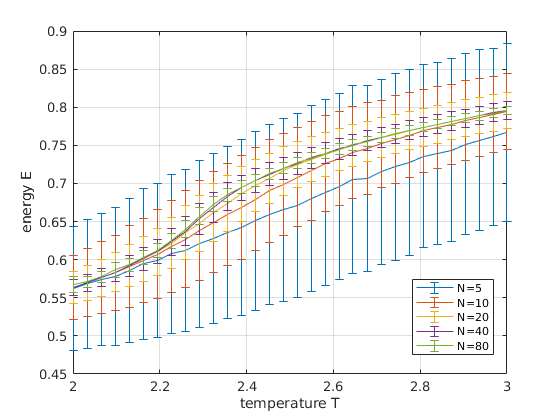

figure(1)
clf
errorbar(temp_red,en1_mean,en1_std,"DisplayName","N="+N1)
hold on
errorbar(temp_red,en2_mean,en2_std,"DisplayName","N="+N2)
errorbar(temp_red,en3_mean,en3_std,"DisplayName","N="+N3)
errorbar(temp_red,en4_mean,en4_std,"DisplayName","N="+N4)
errorbar(temp_red,en5_mean,en5_std,"DisplayName","N="+N5)
grid on
xlabel("temperature T")
ylabel("energy E")
legend("Location","best")

## Auto-Correlation-length energy

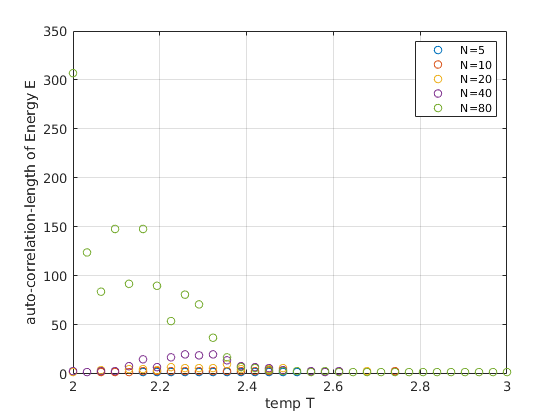

figure(1)
clf
scatter(temp_red,en1_corr,"DisplayName","N="+N1);
hold on
scatter(temp_red,en2_corr,"DisplayName","N="+N2);
scatter(temp_red,en3_corr,"DisplayName","N="+N3);
scatter(temp_red,en4_corr,"DisplayName","N="+N4);
scatter(temp_red,en5_corr,"DisplayName","N="+N5);
box on
grid on
ylabel("auto-correlation-length of Energy E")
xlabel("temp T")
legend()

## Absolute Magnetization: Reduce data to mean and std

[mag1_mean_abs,mag1_std,mag1_var,mag1_var_err,mag1_weight,mag1_corr] = ReduceObservable(abs(mag1),temp1);
[mag2_mean_abs,mag2_std,mag2_var,mag2_var_err,mag2_weight,mag2_corr] = ReduceObservable(abs(mag2),temp1);
[mag3_mean_abs,mag3_std,mag3_var,mag3_var_err,mag3_weight,mag3_corr] = ReduceObservable(abs(mag3),temp1);
[mag4_mean_abs,mag4_std,mag4_var,mag4_var_err,mag4_weight,mag4_corr] = ReduceObservable(abs(mag4),temp1);
[mag5_mean_abs,mag5_std,mag5_var,mag5_var_err,mag5_weight,mag5_corr] = ReduceObservable(abs(mag5),temp1);

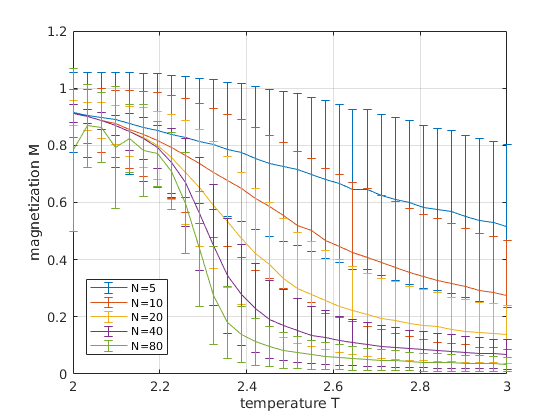

figure(1)
clf
errorbar(temp_red,mag1_mean_abs,mag1_std,"DisplayName","N="+N1)
hold on
errorbar(temp_red,mag2_mean_abs,mag2_std,"DisplayName","N="+N2)
errorbar(temp_red,mag3_mean_abs,mag3_std,"DisplayName","N="+N3)
errorbar(temp_red,mag4_mean_abs,mag4_std,"DisplayName","N="+N4)
errorbar(temp_red,mag5_mean_abs,mag5_std,"DisplayName","N="+N5)
grid on
xlabel("temperature T")
ylabel("magnetization M")
legend("Location","best")

## Auto-Correlation-length magnetization

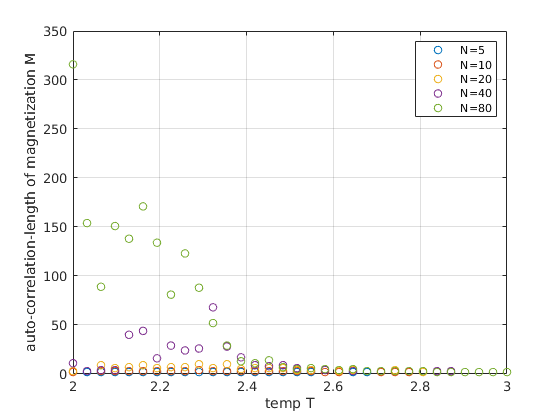

figure(1)
clf
scatter(temp_red,mag1_corr,"DisplayName","N="+N1);
hold on
scatter(temp_red,mag2_corr,"DisplayName","N="+N2);
scatter(temp_red,mag3_corr,"DisplayName","N="+N3);
scatter(temp_red,mag4_corr,"DisplayName","N="+N4);
scatter(temp_red,mag5_corr,"DisplayName","N="+N5);
box on
grid on
ylabel("auto-correlation-length of magnetization M")
xlabel("temp T")
legend()

## heatCapacity

heatC1=en1_var./temp_red.^2.*N1.^2;
heatC2=en2_var./temp_red.^2.*N2.^2;
heatC3=en3_var./temp_red.^2.*N3.^2;
heatC4=en4_var./temp_red.^2.*N4.^2;
heatC5=en5_var./temp_red.^2.*N5.^2;

heatC1_err=en1_var_err./temp_red.^2.*N1.^2.*en1_corr;
heatC2_err=en2_var_err./temp_red.^2.*N2.^2.*en2_corr;
heatC3_err=en3_var_err./temp_red.^2.*N3.^2.*en3_corr;
heatC4_err=en4_var_err./temp_red.^2.*N4.^2.*en4_corr;
heatC5_err=en5_var_err./temp_red.^2.*N5.^2.*en5_corr;

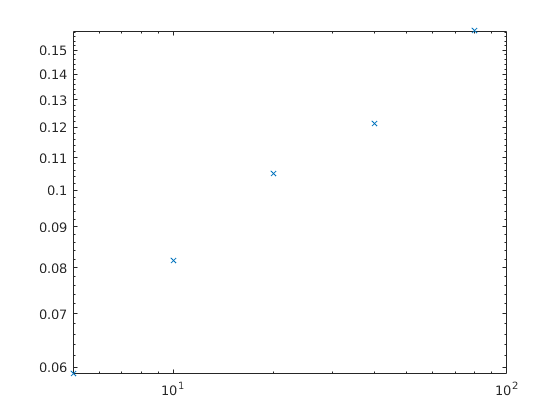

figure(4)
clf
loglog([N1,N2,N3,N4,N5],[max(heatC1),max(heatC2),max(heatC3),max(heatC4),max(heatC5)],'x')

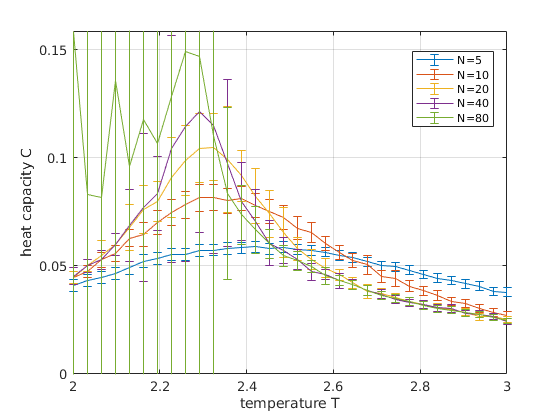

figure(4)
clf
errorbar(temp_red,heatC1,heatC1_err,"DisplayName","N="+N1)
hold on
errorbar(temp_red,heatC2,heatC2_err,"DisplayName","N="+N2)
errorbar(temp_red,heatC3,heatC3_err,"DisplayName","N="+N3)
errorbar(temp_red,heatC4,heatC4_err,"DisplayName","N="+N4)
errorbar(temp_red,heatC5,heatC5_err,"DisplayName","N="+N5)
grid on
box on
%xlim([1,3.5])
ylim([0,max(heatC5)])
xlabel("temperature T")
ylabel("heat capacity C")
legend("Location","best")

## Susceptibility

chi1=mag1_var./temp_red.*N1.^2;
chi2=mag2_var./temp_red.*N2.^2;
chi3=mag3_var./temp_red.*N3.^2;
chi4=mag4_var./temp_red.*N4.^2;
chi5=mag5_var./temp_red.*N5.^2;

chi1_err=mag1_var_err./temp_red.*N1.^2.*mag1_corr;
chi2_err=mag2_var_err./temp_red.*N2.^2.*mag2_corr;
chi3_err=mag3_var_err./temp_red.*N3.^2.*mag3_corr;
chi4_err=mag4_var_err./temp_red.*N4.^2.*mag4_corr;
chi5_err=mag5_var_err./temp_red.*N5.^2.*mag5_corr;

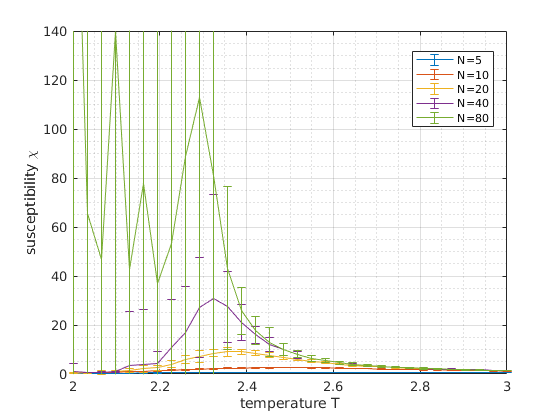

figure(5)
clf
errorbar(temp_red,chi1,chi1_err,"DisplayName","N="+N1)
hold on
errorbar(temp_red,chi2,chi2_err,"DisplayName","N="+N2)
errorbar(temp_red,chi3,chi3_err,"DisplayName","N="+N3)
errorbar(temp_red,chi4,chi4_err,"DisplayName","N="+N4)
errorbar(temp_red,chi5,chi5_err,"DisplayName","N="+N5)
grid on
grid minor
box on
%xlim([1.5,3.5])
ylim([0,max(chi5(3:end))])
xlabel("temperature T")
ylabel("susceptibility \chi")
legend("Location","best")

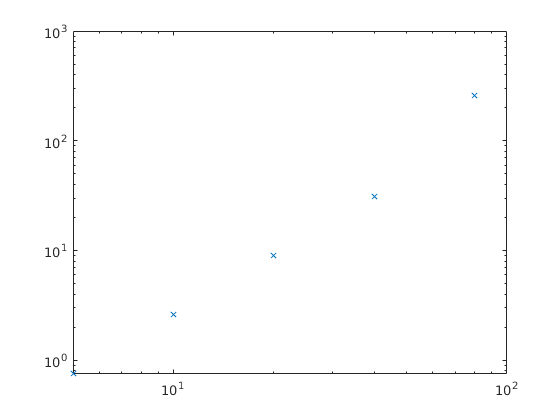

figure(5)
clf
loglog([N1,N2,N3,N4,N5],[max(chi1),max(chi2),max(chi3),max(chi4),max(chi5)],'x')